## Homework 4: Graph Spectra

#### `Team Members: Noel Karlsson Johansson, Alexander Olsson`

### `Instructions:`

`1. Download the dataset from the link on canvas`

`2. Place the file in the same directory as this file`

`3. Run the code`

## Read data

clear all
k_1 = 4;
k_2 = 2;
E_1 = csvread('example1.dat');
E_2 = csvread('example2.dat');


## Step 1

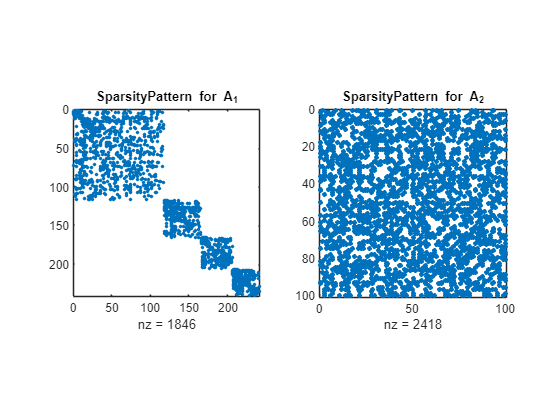


A_1 = step1(E_1,k_1);
A_2 = step1(E_2,k_2);
% Plot
figure(1);
subplot(1,2,1);
spy(A_1)
title("SparsityPattern for A_1")
subplot(1,2,2);
spy(A_2)
title("SparsityPattern for A_2")

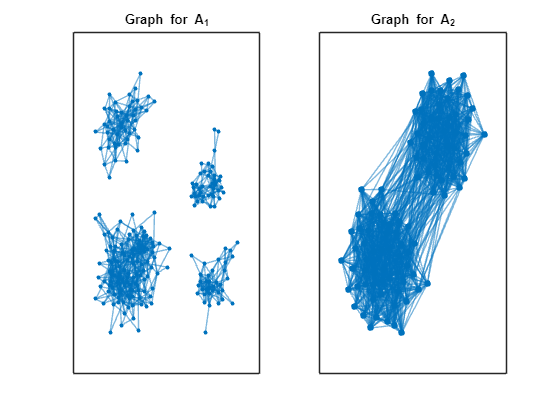

figure(2);
subplot(1,2,1);
plot(graph(A_1), 'Layout','force');
title("Graph for A_1")
subplot(1,2,2);
plot(graph(A_2),'Layout', 'force', 'NodeLabel', {});
title("Graph for A_2")

%h=plot(graph(A), 'Layout','force');

## Step 2-5

%clusters_1 = step2_5(A_1, K_1)
%clusters_2 = step2_5(A_2, K_2)
D = diag(sum(A,2));

Unrecognized function or variable 'A'.

L = (D^(-1/2))*A*(D^(-1/2));

%% Step 3
[v, D] = eigs(L, k);

%% Step 4
Y = v./sum(v.*v,2).^(1/2);

%% Step 5
clusters = kmeans(Y, k);

%% Step 6
% Assign different colors to each cluster
colors = hsv(k);
cluster_colors = colors(clusters, :);
h.NodeCData = clusters;
figure;
% Display colorbar
title("Colored Graph")
colorbar;
[V,D] = eigs(L, 2, 'SA');
plot(sort(V(:,2)), '-');
title("Sorted Fiedler Vector")


### Functions

function [A] = step1(E,k)
    col1 = E(:,1);
    col2 = E(:,2);
    max_ids = max(max(col1,col2));
    As= sparse(col1, col2, 1, max_ids, max_ids); 
    A = full(adjacency(graph(As)));
end
function [clusters] = step2_5(A, k)
    D = diag(sum(A,2));
    L = (D^(-1/2))*A*(D^(-1/2));
    
    %% Step 3
    [v, D] = eigs(L, k);
    
    %% Step 4
    Y = v./sum(v.*v,2).^(1/2);
    
    %% Step 5
    clusters = kmeans(Y, k);
end